assert(endsWith(pwd, "\non-ferromagnetic metal disk in time domain"), 'Not in project directory')
addpath('../../DCS_functions')

clear

## Distributed Current Source

#### Coil

Coil.num = 2;
Coil.inner_radius = 3.75e-3 * [1 1]; % (m)
Coil.outer_radius = 6.00e-3 * [1 1]; % (m)
Coil.length       = 4.00e-3 * [1 1]; % (m)
Coil.z            = [5.00e-3 10.00e-3]; % (m)

Coil.wire_diameter = 0.35e-3 * [1 1]; % (m)
Coil.N_turns       = 60 * [1 1];
Coil.conductivity  = 6e7 * [1 1];    % (S/m)

#### Sensor

Sensor.num = 1;
Sensor.side_length = 0.8e-3;

Sensor.position = [0e-3 2.5e-3]';

#### Model

disk.radius = 30e-3; % (m)
disk.height = 6e-3; % (m)
disk.n_r = 20; % number of elements in r direction
disk.n_z = 10; % number of elements in z direction

r = linspace(0, disk.radius, disk.n_r+1);
z = linspace(-disk.height,0, disk.n_z+1);

Model = BuildModel2D('Cylinder', r,z);

build model took 0.02 seconds


clear disk r z

Model.conductivity = 3.57e7 * ones(1,Model.num_elems); % (S/m)
Model.relative_permittivity = 1 * ones(1,Model.num_elems); % (1)
Model.relative_permeability = 1 * ones(1,Model.num_elems); % (1)

#### Governing equation

GoverningEquation = BuildGoveringEquation2D(Model, Coil, Sensor);

build governing equation took 6.30 seconds


#### Solve in time domain

V_E = 1;
pulse_width = 3e-3; % (s)
Coil.time_domain.excitation = {
    "Voltage",     @(t) V_E * (t <= pulse_width)
    "dCurrent_dt", @(t) 0                        };
Coil.time_domain.time_span = [0, 6e-3]; % (s)
clear V_E pulse_width

% I_E = 1;
% f = 2000; % (Hz)
% omega = 2*pi*f;
% Coil.time_domain.excitation = {
%     "dCurrent_dt", @(t) I_E * omega*cos(omega*t)
%     "dCurrent_dt", @(t) 0                        };
% Coil.time_domain.time_span = [0, 5e-4]; % (s)
% clear I_E f omega

Model.conductivity = 3.57e7 * ones(1,Model.num_elems); % (S/m)
GoverningEquation = BuildGoveringEquation2D(GoverningEquation, Model);
[Model, Coil, Sensor] = SolveTimeDomain2D(GoverningEquation, Model, Coil, Sensor);

solve in time domain took 1.17 seconds


#### Plot world

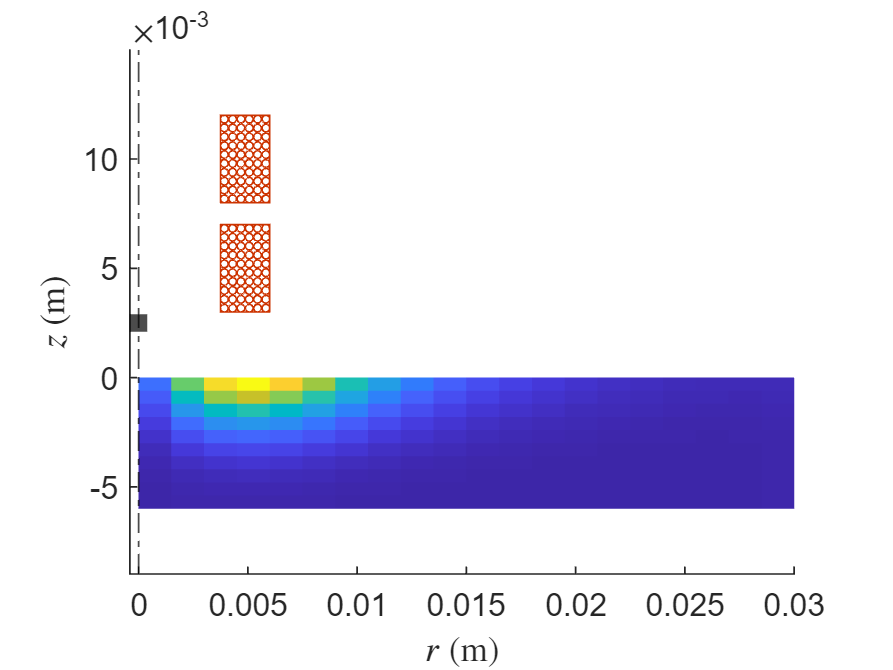

t = 0.1e-3; % (s)
[~,k] = min(abs(t - Model.time_domain.t));

figure
PlotWorld2D(Model, Coil, Sensor, abs(Model.time_domain.J(:,:,k)) );


clear t k

#### Plot coil current and voltage

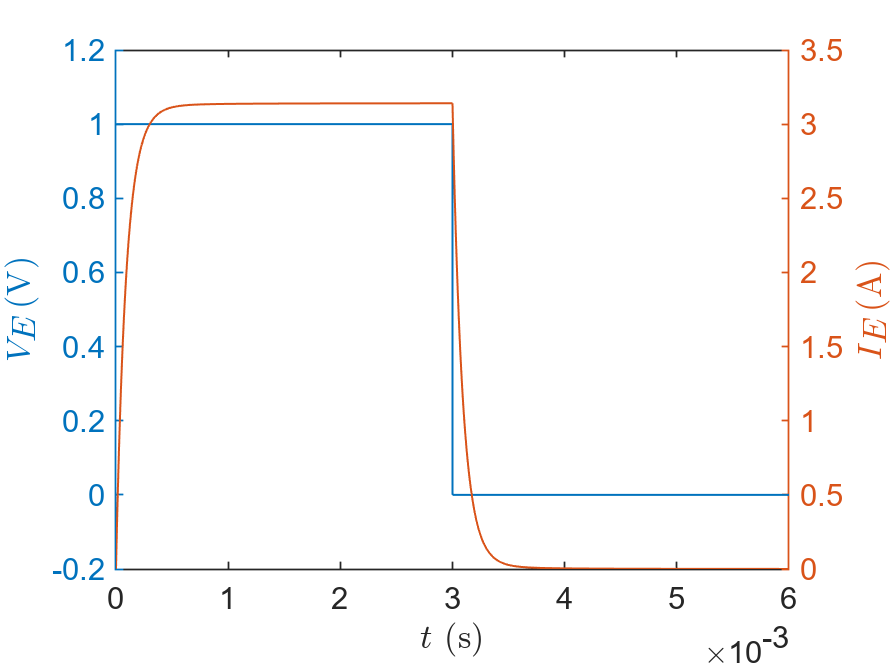

figure
yyaxis left
plot(Sensor.time_domain.t, squeeze(Coil.time_domain.V(1,1,:)))
ylabel('$V_E$ (V)', 'Interpreter','latex')
yyaxis right
plot(Sensor.time_domain.t, squeeze(Coil.time_domain.I(1,1,:)));
ylabel('$I_E$ (A)', 'Interpreter','latex')
xlabel('$t$ (s)', 'Interpreter','latex')

## Compare with FEA

#### Read data

if strcmpi(Coil.time_domain.excitation{1,1}, 'dcurrent_dt')

data = readmatrix('FEA_data\current_excitation.txt', 'CommentStyle','%');
FEA.t = unique(data(:,2));
FEA.B_z = reshape(data(:,3), length(FEA.t), []);
FEA.B_E_z = FEA.B_z(:,end);
FEA.B_C_z = FEA.B_z - FEA.B_E_z;

FEA_B_E_z = FEA.B_E_z;
FEA_B_C_z = FEA.B_C_z(:,4);

end

if strcmpi(Coil.time_domain.excitation{1,1}, 'voltage')

data = readmatrix('FEA_data\voltage_excitation.txt', 'CommentStyle','%');
FEA.t = unique(data(:,2));
FEA.B_z = reshape(data(:,3), length(FEA.t), []);
FEA.I   = reshape(data(:,4), length(FEA.t), []);
FEA.B_E_z = FEA.I / max(FEA.I(:,end)) * max(FEA.B_z(:,end));
FEA.B_C_z = FEA.B_z - FEA.B_E_z;

FEA_B_E_z = FEA.B_E_z(:,4);
FEA_B_C_z = FEA.B_C_z(:,4);

end

clear data

#### Magnetic flux density

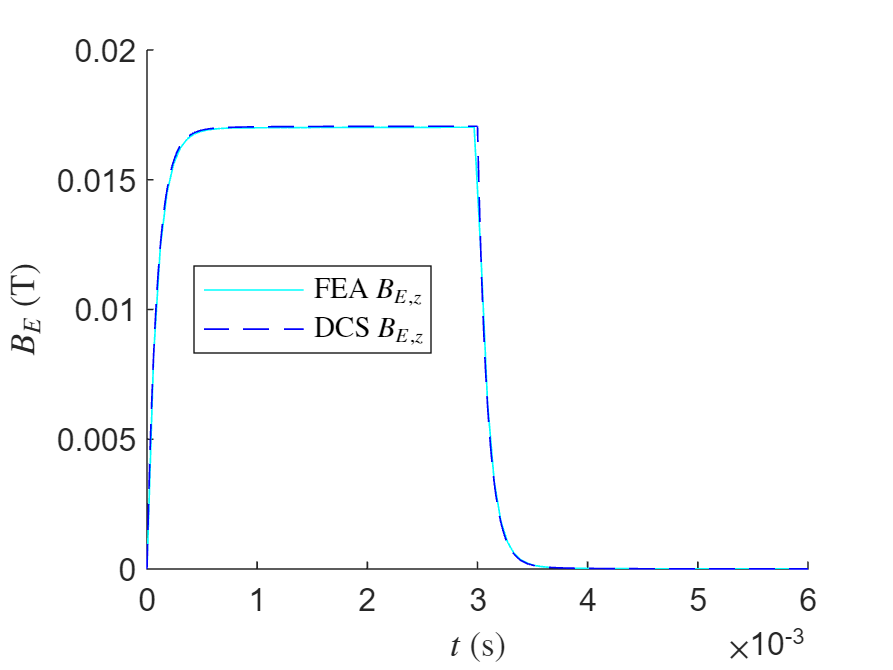

figure
hold on
plot(FEA.t, FEA_B_E_z, 'c-', 'DisplayName','FEA $B_{E,z}$')
plot(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_E(2,1,:)), 'b--', 'DisplayName','DCS $B_{E,z}$');
legend('show', 'Location','best', 'Interpreter','latex')
xlabel("$t$ (s)", 'Interpreter','latex')
ylabel("$B_E$ (T)", 'Interpreter','latex')

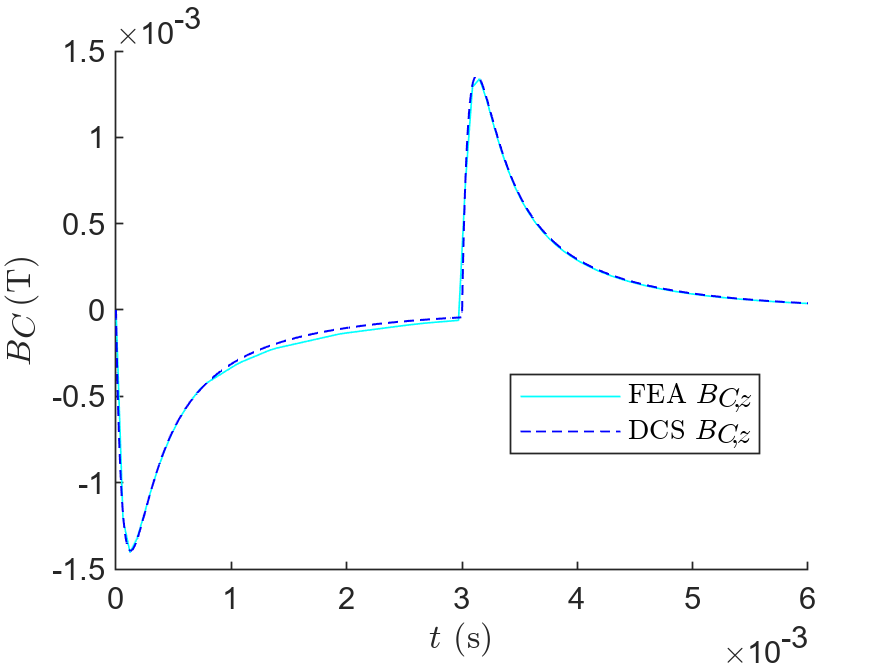


figure
hold on
plot(FEA.t, FEA_B_C_z, 'c-', 'DisplayName','FEA $B_{C,z}$')
plot(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_C(2,1,:)), 'b--', 'DisplayName','DCS $B_{C,z}$');
legend('show', 'Location','best', 'Interpreter','latex')
xlabel("$t$ (s)", 'Interpreter','latex')
ylabel("$B_C$ (T)", 'Interpreter','latex')


DCS_B_C_z = interp1(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_C(2,1,:)), FEA.t);
error = mean(abs(DCS_B_C_z - FEA_B_C_z)) / mean(abs(FEA_B_C_z));
fprintf('error: %f%%\n', error*100);

error: 3.777575%



clear FEA_B_E_z FEA_B_C_z DCS_B_C_z error

## Material Sweep

#### Solve in time domain

materials      = ["Ti"    "Zn"   "Mo"   "Al"   "Cu"  ];
conductivities = [0.238e7 1.69e7 1.91e7 3.57e7 5.96e7];
colors         = ['r'     'g'    'b'    'k'    'y'   ];

figure
hold on
for i = 1:numel(materials)
    Model.conductivity = conductivities(i) * ones(1,Model.num_elems);
    GoverningEquation = BuildGoveringEquation2D(GoverningEquation, Model);

    [Model, Coil, Sensor] = SolveTimeDomain2D(GoverningEquation, Model, Coil, Sensor);

    label = sprintf('FEA %s', materials(i));
    plot(FEA.t, FEA.B_C_z(:,i), '-', 'DisplayName',label, 'Color',colors(i));

    label = sprintf('DCS %s', materials(i));
    plot(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_C(2,1,:)), '--', 'DisplayName',label, 'Color',colors(i));
end

solve in time domain took 0.30 seconds
solve in time domain took 0.27 seconds
solve in time domain took 1.10 seconds
solve in time domain took 1.02 seconds
solve in time domain took 1.20 seconds


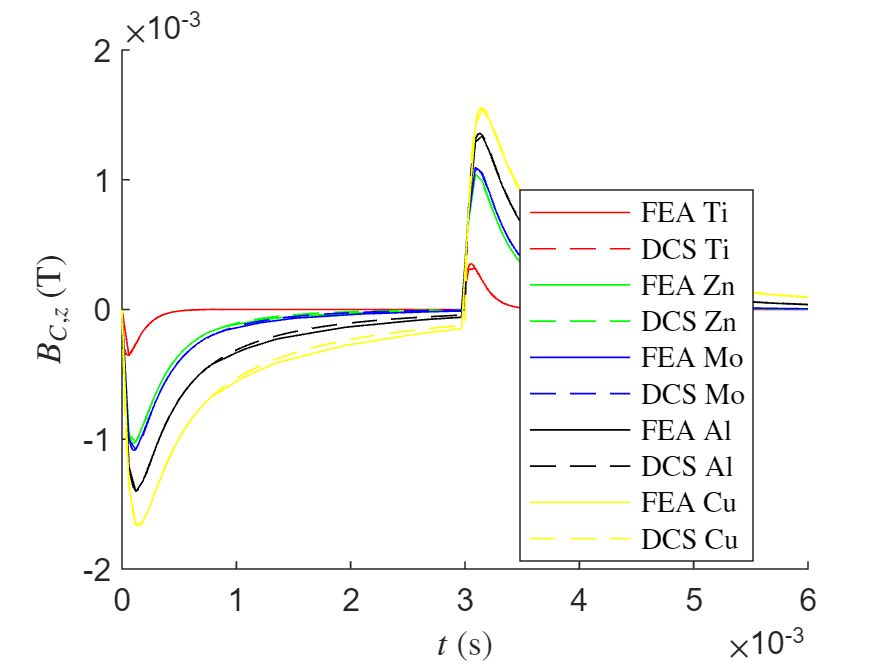

legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$t$ (s)", 'Interpreter','latex')
ylabel("$B_{C,z}$ (T)", 'Interpreter','latex')


clear materials conductivities colors i label